This example explores a transfer from high Earth orbit to high lunar orbit.

First we define the satellite's characteristics. Approximately a 9U cubesat.

area = 1;       % m2
ref = 0.08;     % NA
initMass = 10;  % kg
endMass = 8;    % kg
isp = 2150;     % s
g0 = 9.80665;   % m/s2
exhVel = isp * g0;
thrust = 0.001; % N
mDot = 52e-9;   % kg/s

We specify the orbital elements. This orbit is specifically aligned with the Moon to achieve the capture.

earthRadius = 6378136.3;    % m
p = 1.35e8; f = 3.6e8; sma = (p+f)/2; ecc = (f-p)/(f+p);
[inc,RAAN,aop,true_an] = deal(29, 0, 135, -85);
startDate = juliandate(datetime(2024, 03, 01));

IMPORTANT: Remember to open the Simulink file and properly connect the correct maneuvre logic.

% open_system('propagatorMain.slx');
thrustingThresholdMn = 0.999;
burnOverride = 0;

Now choose a simulation length and run it.

tf = 40* 24 * 3600;
tic;
simOut = sim('propagatorMain.slx');


Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 1.5569s


toc

Elapsed time is 11.704923 seconds.


We extract the data from the simulation. This being the satellite's position and the Moon's position in order to obtain a trajectory line.

tsSat = simOut.yout{1}.Values;
ttSat = timeseries2timetable(tsSat);
tsMoon = simOut.yout{7}.Values;
ttMoon = timeseries2timetable(tsMoon);

To avoid conflicts with the viewer's trajectory representation, we retime the timetables manually.

ttSat = retime(ttSat,'minutely');
ttMoon = retime(ttMoon,'minutely');

Raw plot. First ICRF then MCI.

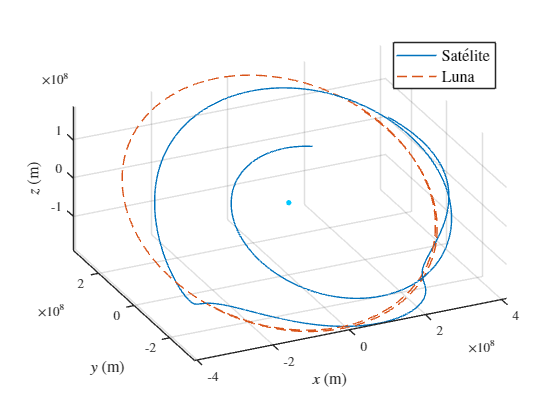

% ICRF
tic
figure
[X,Y,Z] = sphere();
s = surf(X*earthRadius, Y*earthRadius, Z*earthRadius); % plot Earth at the centre
set(s, 'edgecolor', 'none', 'FaceColor', [0,200,255]./255, 'HandleVisibility', 'off')
hold on
plot3(ttSat.Data(:,1), ttSat.Data(:,2), ttSat.Data(:,3), DisplayName="$\mathrm{Sat\acute{e}lite}$")
plot3(ttMoon.Data(:,1), ttMoon.Data(:,2), ttMoon.Data(:,3), '--', DisplayName='$\mathrm{Luna}$')
legend(Interpreter="latex", FontSize=12, Location="northeast")
axis equal
daspect([1 1 1])
view([-25 25])
xlabel('$x$ $(\mathrm{m})$',Interpreter='latex', FontSize=12)
ylabel('$y$ $(\mathrm{m})$',Interpreter='latex', FontSize=12)
zlabel('$z$ $(\mathrm{m})$',Interpreter='latex', FontSize=12)
set(gca,'TickLabelInterpreter','latex')

toc

Elapsed time is 0.296422 seconds.


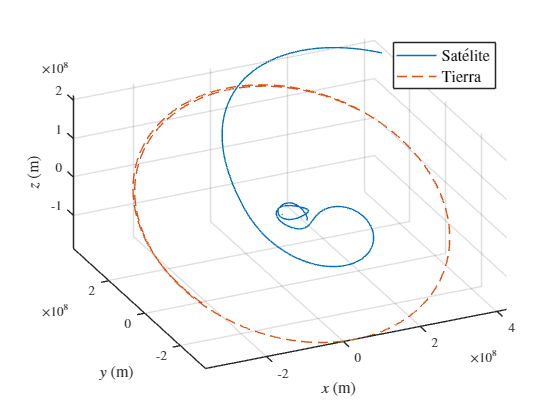

% MCI
tic
moonRadius = 1737e3;
figure
[X,Y,Z] = sphere();
s = surf(X*moonRadius, Y*moonRadius, Z*moonRadius); % plot the Moon at the centre
set(s, 'edgecolor', 'none', 'FaceColor', [100,100,100]./255, 'HandleVisibility', 'off')
hold on
plot3(ttSat.Data(:,1)-ttMoon.Data(:,1), ...
    ttSat.Data(:,2)-ttMoon.Data(:,2), ttSat.Data(:,3)-ttMoon.Data(:,3), DisplayName="$\mathrm{Sat\acute{e}lite}$")
plot3(-ttMoon.Data(:,1), -ttMoon.Data(:,2), -ttMoon.Data(:,3), '--', DisplayName='$\mathrm{Tierra}$')
legend(Interpreter="latex", FontSize=12, Location="northeast")
axis equal
daspect([1 1 1])
view([-25 25])
xlabel('$x$ $(\mathrm{m})$',Interpreter='latex', FontSize=12)
ylabel('$y$ $(\mathrm{m})$',Interpreter='latex', FontSize=12)
zlabel('$z$ $(\mathrm{m})$',Interpreter='latex', FontSize=12)
set(gca,'TickLabelInterpreter','latex')

toc

Elapsed time is 0.120937 seconds.


Since the simulation time is reasonably low, we can try to visualise the trajectory with a fancier viewer. Mileage may vary depending on the strength of the computer being used.

Set up the viewer.

t0 = datetime(2024, 03, 01);
tfin = t0 + seconds(tf);
sample_time = 60;
sc = satelliteScenario(t0,tfin,sample_time);

Create the satellite.

sat = satellite(sc,ttSat,Name = "Spacecraft");

Add the Moon to the visualisation.

moon = satellite(sc,ttMoon,Name= "Moon");
moon.Orbit.LineColor = 'red';
moon.MarkerColor = 'red';

Start the visualisation.

v = satelliteScenarioViewer(sc,CameraReferenceFrame = "Inertial");
play(sc)
camtarget(v,moon); % centres the viewer on the Moon. comment out to disable.